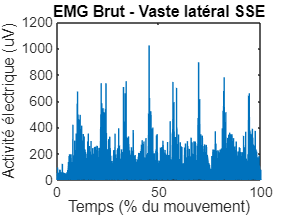

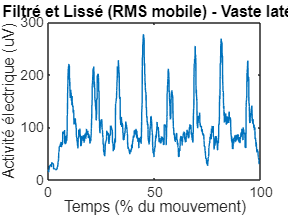

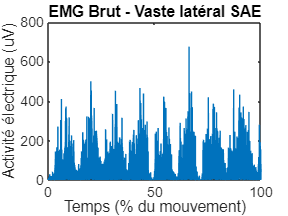

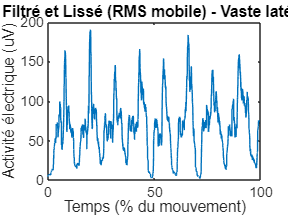

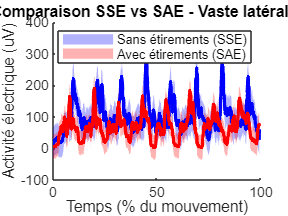

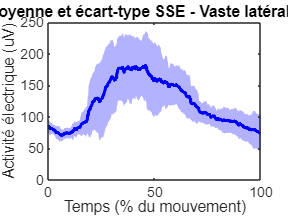

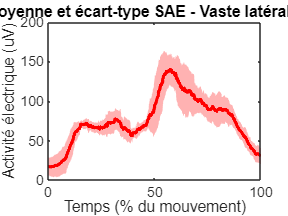

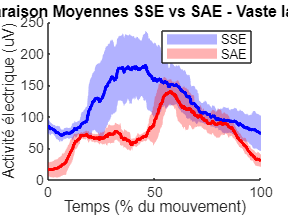

% Fonction pour traiter et visualiser un muscle (sans normalisation CMV, lissage RMS mobile)

function [temps_pourcentage_lisse, data_filt_lisse] = traiter_muscle(data, nom_muscle, condition)



    data(isnan(data) | isinf(data)) = []; 
    n_samples = length(data);
    temps_pourcentage = (0:n_samples-1) / (n_samples-1) * 100;

    figure('Name', ['EMG Brut - ', nom_muscle, ' ', condition]);
    plot(temps_pourcentage, data);
    title(['EMG Brut - ', nom_muscle, ' ', condition]);
    xlabel('Temps (% du mouvement)');
    ylabel('Activité électrique (uV)');


    fs = 1000; 
    low_cutoff = 400; 
    [b_lp, a_lp] = butter(4, low_cutoff / (fs / 2), 'low');
    data_filt = filtfilt(b_lp, a_lp, data);

    windowSize = 200; 
    stepSize = 1; 
    n = length(data_filt);
    data_filt_lisse = zeros(1, n - windowSize + 1); 
    for k = 1:stepSize:n - windowSize + 1
        window = data_filt(k:k + windowSize - 1);
        data_filt_lisse(1 + (k - 1) / stepSize) = rms(window);
    end
    temps_pourcentage_lisse = temps_pourcentage(1:stepSize:n - windowSize + 1);

    figure('Name', ['EMG Filtré - ', nom_muscle, ' ', condition]);
    plot(temps_pourcentage_lisse, data_filt_lisse);
    title(['EMG Filtré et Lissé (RMS mobile) - ', nom_muscle, ' ', condition]);
    xlabel('Temps (% du mouvement)');
    ylabel('Activité électrique (uV)');
end


% Script principal

% 1. Définition des paramètres

sujet = 'AYMERIC';
muscles = {'Vaste latéral', 'Vaste médial', 'Biceps fémoral','Semi-tendineux'}; % Liste de TOUS les muscles
all_muscles = {'Semi-tendineux', 'Vaste médial', 'Biceps fémoral', 'Vaste latéral'}; % Ordre dans le fichier CSV
data_path_SSE = ['Squat_SSE_', sujet, '.csv'];
data_path_SAE = ['Squat_SAE_', sujet, '.csv'];
nReps = 8; % Nombre de répétitions

% Variables pour stocker les temps de coupe du Vaste latéral

temps_coupe_VL_SSE = cell(1, nReps);
temps_coupe_VL_SAE = cell(1, nReps);

% 2. Boucle principale pour chaque muscle

for i = 1:length(muscles)
    current_muscle = muscles{i};
    muscle_index = find(strcmp(all_muscles, current_muscle));

    % 3. Chargement des données

    try
        data_SSE = importdata(data_path_SSE).data(:, muscle_index);
        data_SAE = importdata(data_path_SAE).data(:, muscle_index);
    catch
        warning('Fichier de données non trouvé pour %s. Passage au muscle suivant.', current_muscle);
        continue;
    end

    % 4. Traitement des données SSE et SAE

    [temps_pourcentage_SSE, data_filt_lisse_SSE] = traiter_muscle(abs(data_SSE), current_muscle, 'SSE');
    [temps_pourcentage_SAE, data_filt_lisse_SAE] = traiter_muscle(abs(data_SAE), current_muscle, 'SAE');

    if strcmp(current_muscle, 'Vaste latéral')
        data_filt_lisse_VL_SSE = data_filt_lisse_SSE; % Sauvegarde des données du Vaste Latéral pour la découpe automatique
        data_filt_lisse_VL_SAE = data_filt_lisse_SAE;
        temps_pourcentage_VL_SSE = temps_pourcentage_SSE;
        temps_pourcentage_VL_SAE = temps_pourcentage_SAE;
    end

    % 5. Comparaison SSE et SAE (Adaptée au lissage RMS)

    n_max = max(length(data_filt_lisse_SSE), length(data_filt_lisse_SAE));
    temps_interp = linspace(min(temps_pourcentage_SSE(1), temps_pourcentage_SAE(1)), max(temps_pourcentage_SSE(end), temps_pourcentage_SAE(end)), n_max);
    sse_interp = interp1(temps_pourcentage_SSE, data_filt_lisse_SSE, temps_interp, 'spline');
    sae_interp = interp1(temps_pourcentage_SAE, data_filt_lisse_SAE, temps_interp, 'spline');

    err_sse = std(data_filt_lisse_SSE);
    err_sae = std(data_filt_lisse_SAE);

    figure('Name', ['Comparaison SSE vs SAE - ', current_muscle]);
    hold on;
    fill([temps_interp fliplr(temps_interp)], [sse_interp + err_sse, fliplr(sse_interp - err_sse)], 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    fill([temps_interp fliplr(temps_interp)], [sae_interp + err_sae, fliplr(sae_interp - err_sae)], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    plot(temps_interp, sse_interp, 'b', 'LineWidth', 2);
    plot(temps_interp, sae_interp, 'r', 'LineWidth', 2);
    title(['Comparaison SSE vs SAE - ', current_muscle, ' (uV)']);
    legend('Sans étirements (SSE)', 'Avec étirements (SAE)');
    xlabel('Temps (% du mouvement)');
    ylabel('Activité électrique (uV)');
    hold off;

    % 6. Traitement des répétitions

    repetitions_SSE = cell(1, nReps);
    repetitions_SAE = cell(1, nReps);

    if strcmp(current_muscle, 'Vaste latéral') %  ginput seulement pour le Vaste Latéral

        % Sélection manuelle des répétitions pour Vaste Latéral (avec ginput) - SSE

        figure('Name', ['Sélection Répétitions SSE - ', current_muscle]);
        plot(temps_pourcentage_SSE, data_filt_lisse_SSE);
        title(['Sélection des répétitions pour ', current_muscle, ' SSE']);
        xlabel('Temps (% du mouvement)');
        ylabel('Activité électrique (uV)');

        for j = 1:nReps
            [x_rep, ~] = ginput(2);
            x_rep = round(x_rep * length(data_filt_lisse_SSE) / 100);
            x_rep = sort(x_rep);
            x_rep(1) = max(1, x_rep(1));
            x_rep(2) = min(length(data_filt_lisse_SSE), x_rep(2));
            temps_coupe_VL_SSE{j} = x_rep;
            repetitions_SSE{j} = data_filt_lisse_SSE(x_rep(1):x_rep(2));
        end

        % Sélection manuelle des répétitions pour Vaste Latéral (avec ginput) - SAE

        figure('Name', ['Sélection Répétitions SAE - ', current_muscle]);
        plot(temps_pourcentage_SAE, data_filt_lisse_SAE);
        title(['Sélection des répétitions pour ', current_muscle, ' SAE']);
        xlabel('Temps (% du mouvement)');
        ylabel('Activité électrique (uV)');

        for j = 1:nReps
            [x_rep, ~] = ginput(2);
            x_rep = round(x_rep * length(data_filt_lisse_SAE) / 100);
            x_rep = sort(x_rep);
            x_rep(1) = max(1, x_rep(1));
            x_rep(2) = min(length(data_filt_lisse_SAE), x_rep(2));
            temps_coupe_VL_SAE{j} = x_rep;
            repetitions_SAE{j} = data_filt_lisse_SAE(x_rep(1):x_rep(2));
        end

    else % Découpe automatique pour les autres muscles

        for j = 1:nReps
            x_rep_sse = round(temps_coupe_VL_SSE{j} * length(data_filt_lisse_SSE) / length(data_filt_lisse_VL_SSE));
            x_rep_sae = round(temps_coupe_VL_SAE{j} * length(data_filt_lisse_SAE) / length(data_filt_lisse_VL_SAE));

            x_rep_sse = sort(x_rep_sse);
            x_rep_sse(1) = max(1, x_rep_sse(1));
            x_rep_sse(2) = min(length(data_filt_lisse_SSE), x_rep_sse(2));

            x_rep_sae = sort(x_rep_sae);
            x_rep_sae(1) = max(1, x_rep_sae(1));
            x_rep_sae(2) = min(length(data_filt_lisse_SAE), x_rep_sae(2));

            repetitions_SSE{j} = data_filt_lisse_SSE(x_rep_sse(1):x_rep_sse(2));
            repetitions_SAE{j} = data_filt_lisse_SAE(x_rep_sae(1):x_rep_sae(2));
        end
    end

    % Interpolation des répétitions

    maxLength = max(max(cellfun(@length, repetitions_SSE)), max(cellfun(@length, repetitions_SAE)));
    temps_interp_reps = linspace(0, 100, maxLength);
    repsSSE_interp = zeros(nReps, maxLength);
    repsSAE_interp = zeros(nReps, maxLength);

    for j = 1:nReps
        repsSSE_interp(j,:) = interp1(linspace(0, 100, length(repetitions_SSE{j})), repetitions_SSE{j}, temps_interp_reps, 'spline');
        repsSAE_interp(j,:) = interp1(linspace(0, 100, length(repetitions_SAE{j})), repetitions_SAE{j}, temps_interp_reps, 'spline');
    end

    % Calcul des pics pour chaque répétition

    pics_SSE = zeros(nReps, 1);
    pics_SAE = zeros(nReps, 1);

    for j = 1:nReps
        pics_SSE(j) = max(repetitions_SSE{j});
        pics_SAE(j) = max(repetitions_SAE{j});
    end

    % Stockage des pics dans un tableau

    if i == 1 % Initialisation du tableau au premier muscle
        pics_table = table('Size', [nReps * length(muscles), 3], ...
                          'VariableTypes', {'string', 'double', 'string'}, ...
                          'VariableNames', {'Muscle', 'Pic', 'Condition'});
        row_start = 1;
    end

    row_end = row_start + nReps - 1;
    pics_table.Muscle(row_start:row_end) = current_muscle;
    pics_table.Pic(row_start:row_end) = pics_SSE;
    pics_table.Condition(row_start:row_end) = "SSE";

    row_start = row_end + 1;
    row_end = row_start + nReps - 1;
    pics_table.Muscle(row_start:row_end) = current_muscle;
    pics_table.Pic(row_start:row_end) = pics_SAE;
    pics_table.Condition(row_start:row_end) = "SAE";

    row_start = row_end + 1;

    % Calcul des moyennes et écarts-types

    moyenne_SSE = mean(repsSSE_interp, 1);
    moyenne_SAE = mean(repsSAE_interp, 1);
    ecart_type_SSE = std(repsSSE_interp, 1);
    ecart_type_SAE = std(repsSAE_interp, 1);

    % 7. Affichage des moyennes et écarts-types des répétitions

    figure('Name', ['Moyenne et Ecart-Type SSE - ', current_muscle]);
    fill([temps_interp_reps fliplr(temps_interp_reps)], [moyenne_SSE+ecart_type_SSE fliplr(moyenne_SSE-ecart_type_SSE)], 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    hold on;
    plot(temps_interp_reps, moyenne_SSE, 'b', 'LineWidth', 2);
    title(['Moyenne et écart-type SSE - ', current_muscle, ' (uV)']);
    xlabel('Temps (% du mouvement)');
    ylabel('Activité électrique (uV)');
    hold off;

    figure('Name', ['Moyenne et Ecart-Type SAE - ', current_muscle]);
    fill([temps_interp_reps fliplr(temps_interp_reps)], [moyenne_SAE+ecart_type_SAE fliplr(moyenne_SAE-ecart_type_SAE)], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    hold on;
    plot(temps_interp_reps, moyenne_SAE, 'r', 'LineWidth', 2);
    title(['Moyenne et écart-type SAE - ', current_muscle, ' (uV)']);
    xlabel('Temps (% du mouvement)');
    ylabel('Activité électrique (uV)');
    hold off;


    % 8. Affichage combiné des moyennes SSE et SAE

    figure('Name', ['Comparaison Moyennes SSE vs SAE - ', current_muscle]);
    hold on;
    fill([temps_interp_reps fliplr(temps_interp_reps)], [moyenne_SSE+ecart_type_SSE fliplr(moyenne_SSE-ecart_type_SSE)], 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    fill([temps_interp_reps fliplr(temps_interp_reps)], [moyenne_SAE+ecart_type_SAE fliplr(moyenne_SAE-ecart_type_SAE)], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    plot(temps_interp_reps, moyenne_SSE, 'b', 'LineWidth', 2);
    plot(temps_interp_reps, moyenne_SAE, 'r', 'LineWidth', 2);
    title(['Comparaison Moyennes SSE vs SAE - ', current_muscle, ' (uV)']);
    legend('SSE', 'SAE');
    xlabel('Temps (% du mouvement)');
    ylabel('Activité électrique (uV)');
    hold off;


end % Fin de la boucle principale



% Affichage du tableau des pics

disp(pics_table);

         Muscle          Pic      Condition
    ________________    ______    _________

    "Vaste latéral"     220.49      "SSE"  
    "Vaste latéral"     215.42      "SSE"  
    "Vaste latéral"     227.56      "SSE"  
    "Vaste latéral"     276.95      "SSE"  
    "Vaste latéral"      211.2      "SSE"  
    "Vaste latéral"     254.53      "SSE"  
    "Vaste latéral"     268.51      "SSE"  
    "Vaste latéral"     226.64      "SSE"  
    "Vaste latéral"     164.18      "SAE"  
    "Vaste latéral"     190.27      "SAE"  
    "Vaste latéral"     145.55      "SAE"  
    "Vaste latéral"     165.86      "SAE"  
    "Vaste latéral"     153.93      "SAE"  
    "Vaste latéral"     183.63      "SAE"  
    "Vaste latéral"      139.5      "SAE"  
    "Vaste latéral"     159.24      "SAE"  
    "Vaste médial"      139.69      "SSE"  
    "Vaste médial"      153.96      "SSE"  
    "Vaste médial